# Module 3: Localization merging

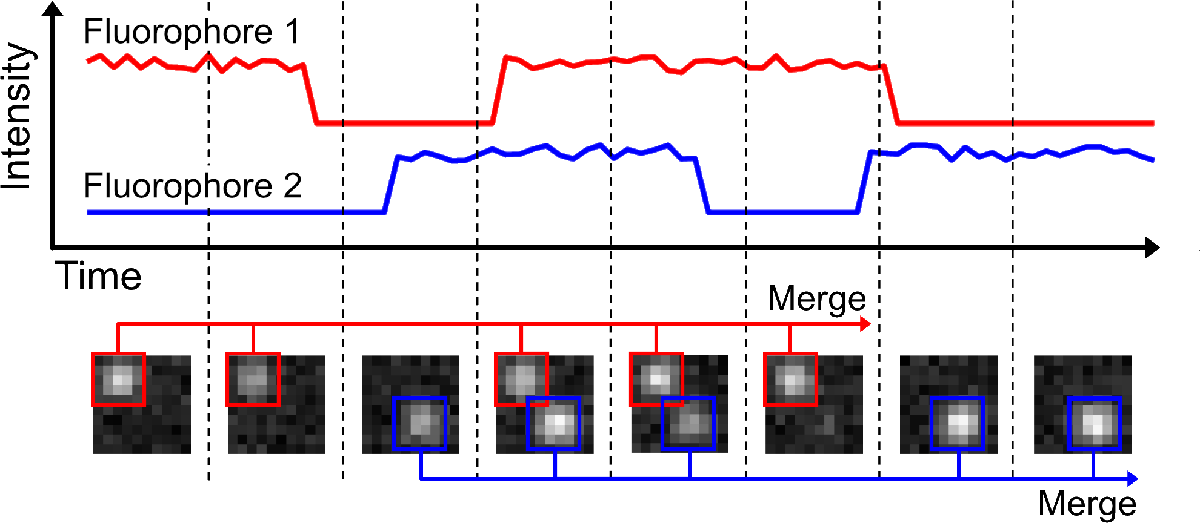

Merging of localizations can be important to accurately quantify molecule or protein numbers, and can help in obtaining better localization accuracy. It is normally caused by fluorescent molecules that are in their 'on' state for more than 1 frame, and thus are the same underlying fluorophore shown in more than 1 frame.

Briefly, localization merging is the process of checking which localizations are (almost) non-moving in consecutive frames, and merging these to a single localization.

## Variable initiation

There are some crucial variables necessary for localization merging. These are:

- Maximum distance: the maximum distance between localizations in consecutive frames (in nm) where they are considered to be 'non-moving'. This value should be slighly larger than the expected localization uncertainty, but it also depends on the localization density and expected fluorophore mobility.

- Maximum off-frames: sometimes a fluorophore can blink for a while, going to a temporary 'off'-state. This variable determines how long (in frames) the localization can be missing while still being merged.

- Maximum length of a fluorophore: if fiducial markers are introduced in the sample, these will normally of course be merged down to a single localization, but it doesn't make sense. This variable will exclude merging of localizations if a single fluorophore stays 'on' for at least this many frames.

%First we load the data 
data = readmatrix('Data/DNAPAINT_LocalizationList.txt');

%Define some variables
maxDistance = 30; %Max distance between points per frame
maxOffFrame = 1; %Max number of frames the localization can be 'off'
maxLength = 500; %Max length of a molecule --> longer than this will be removed - usefull for fiducial markers

## Nearest-neighbour localization finding

The simplest way to think about localization merging is described in this code block. All localizations on frame n are compared to all localizations on frame n+1, and their nearest neighbours are found. Then, if the distance between the localization on frame n and the nearest-neighbour localization on frame n+1 is smaller than a pre-defined distance, they are linked together in a trajectory. Information about a trajectory-ID and the distance between these localizations is stored.

Because this code will be re-used for multiple modules in the future, we designed it to be general, and we explain it step-wise.

First, we create a block of code that does nearest-neighbour localization finding between frame 0 and frame 1, and later we loop over all frames.

%First, we add two empty columns to the data matrix, and store it as
%'tracked_data' matrix. These two empty arrays will get information stored
%about the trajectory ID and the jump distance.
tracked_data = [data zeros(size(data,1),2)];

%We also start two counters: a tracksCounter and a idCounter.
% The tracksCounter will increase when a new trajectory is created.
tracksCounter = 1;

%Now we determine that we do this trajectory finding between two frames, in
%this case frame 0 and frame 1.
frame1 = 8;
frame2 = 9;
%Make sub-matrix of this frame and the next frame
framematrix = tracked_data(tracked_data(:,1)==frame1,:);
nextframematrix = tracked_data(tracked_data(:,1)==frame2,:);

%Now we check that there are localizations in both of these frames - if one
%of the frames does not have localizations, we cannot try to track the
%localizations. Note that we already know that in this case, frame 0 and
%frame 1 have localizations, but this will not always be the case.
if (size(framematrix,1) > 0 && size(nextframematrix,1) > 0)
    %Now we can find all the nearest neighbours between all localizations
    % on this frame and on the next frame
    [neighbourID, neighbourDist] = knnsearch(nextframematrix(:,2:3),framematrix(:,2:3));
    % We store this data in a 2-column array
    foundnn = [neighbourID neighbourDist];

    % Now we have to select only those entries that are < maxDistance. We want
    % to extract the IDs of the localizations in frame n+1 that belong to them.
    NeighbourIDs = foundnn(foundnn(:,2) < maxDistance,1);
    % We also want to extract the ID of the original localizations by
    % finding the row index of the nearest neighbours.
    OriginIDs = find(foundnn(:,2) < maxDistance);

    % For every found neighbour, we make both neighbours the same track-id.
    % First, we check that the neighbour on frame n has or doesn't have an
    % track-id yet, then we set the neighbour on frame n+1
    % to the same value, or to a new track-id if none is assigned yet
    % We loop over all found IDs
    for i = 1:size(NeighbourIDs,1)
        %We get the localization-ID of the neighbour in frame n+1
        neighbourID = NeighbourIDs(i);
        %We also get the localization-ID of the original localization in frame n
        originID = OriginIDs(i);
        %Prevent linkage if the neighbour in frame n+1 is already linked -
        %this will not happen in this example, but it might happen when
        %skipping frames in later modules.
        if nextframematrix(neighbourID,5) == 0
            %We check that the localization that will be included in a trajectory
            %is not yet part of an existing trajectory - if it is part of
            %an existing track, the index in column 5 will be higher than 0
            if framematrix(originID,5) == 0
                %If it's not linked yet, set it and the neighbour to a new track-id value
                framematrix(originID,5) = tracksCounter;
                nextframematrix(neighbourID,5) = tracksCounter;
                tracksCounter = tracksCounter+1;
            else
                %If it is linked, set it to the track-id value of the neighbour in frame n
                nextframematrix(neighbourID,5) = framematrix(originID,5);
            end
            %Finally, we  provide the distance to the next emitter in the
            %track on the next frame
            framematrix(originID,6) = foundnn(originID,2);
        end
    end
end
%Now we have fully filled frame matrix and nextframematrix variables, but
%we need to fill these back in into the original tracked_data matrix. We do
%this by looking up the values via the idCounter value
if size(framematrix,1) > 0
    tracked_data(tracked_data(:,1)==frame1,:) = framematrix;
%     tracked_data(idCounter:idCounter+size(framematrix,1)-1,:) = framematrix;
end
if size(nextframematrix,1) > 0
    tracked_data(tracked_data(:,1)==frame2,:) = nextframematrix;
%     tracked_data(idCounter+size(framematrix,1):idCounter+size(framematrix,1)+size(nextframematrix,1)-1,:) = nextframematrix;
end

We can now see which localizations belong together on these trajectories. Take a look at the 5th column, where the ID of the framematrix and nextframematrix are identical for certain emitters - these are linked together. Also, the distance between these localizations (6th column in framematrix) is lower than the set threshold.

for k = 1:size(framematrix,1)
    fprintf('%.2f %.2f %.2f %.2f %.2f %.2f\n',framematrix(k,:));
end

8.00 62.64 133.37 94826.00 1.00 0.07
8.00 15.64 126.56 133896.40 2.00 0.01
8.00 58.04 123.26 135254.00 3.00 0.10
8.00 33.17 110.64 31138.60 4.00 21.52
8.00 44.13 92.10 115504.80 0.00 0.00
8.00 73.40 91.83 19308.40 5.00 0.23
8.00 27.56 68.90 112477.30 6.00 0.10
8.00 121.28 56.12 154927.70 7.00 0.07
8.00 58.62 42.04 66182.40 0.00 0.00


for k = 1:size(nextframematrix,1)
    fprintf('%.2f %.2f %.2f %.2f %.2f %.2f\n',nextframematrix(k,:));
end

9.00 62.70 133.33 94895.30 1.00 0.00
9.00 116.24 131.04 52668.40 0.00 0.00
9.00 15.64 126.57 127074.10 2.00 0.00
9.00 58.14 123.28 146750.10 3.00 0.00
9.00 73.27 92.02 19109.20 5.00 0.00
9.00 44.09 92.10 107096.00 4.00 0.00
9.00 27.55 69.00 120916.40 6.00 0.00
9.00 121.22 56.16 64884.90 7.00 0.00
9.00 19.42 42.73 58122.50 0.00 0.00


We copy this function to the commonFunctions file, and we can call it this way: 

`[tracked_data,tracksCounter] = creating_trajectories(tracked_data,frame1,frame2,maxDistance,tracksCounter)`

First, we check if everything went well by re-performing the same analysis between frame 0 and 1, and checking that we get the same data output.

%We reset the tracked_data variable
tracked_data = [data zeros(size(data,1),2)];
%We perform tracking between frame 0 and 1
[tracked_data2] = commonFunctions.creating_trajectories(tracked_data,0,1,maxDistance,1);

%We check the data on frame 0
framematrix2_0 = tracked_data2(tracked_data2(:,1)==0,:);
for k = 1:size(framematrix2_0,1)
    fprintf('%.2f %.2f %.2f %.2f %.2f %.2f\n',framematrix2_0(k,:));
end

0.00 62.54 133.36 94719.80 1.00 0.15
0.00 132.64 126.64 158037.50 2.00 0.03
0.00 87.32 97.76 50163.50 3.00 0.40
0.00 58.99 42.04 17653.00 4.00 0.26


%We check the data on frame 1
framematrix2_1 = tracked_data2(tracked_data2(:,1)==1,:);
for k = 1:size(framematrix2_1,1)
    fprintf('%.2f %.2f %.2f %.2f %.2f %.2f\n',framematrix2_1(k,:));
end

1.00 45.27 138.88 15207.50 0.00 0.00
1.00 62.68 133.42 98822.30 1.00 0.00
1.00 132.65 126.67 146704.20 2.00 0.00
1.00 56.93 113.15 25943.20 0.00 0.00
1.00 87.16 98.13 10329.20 3.00 0.00
1.00 58.73 42.07 47259.30 4.00 0.00
1.00 30.00 38.45 10206.40 0.00 0.00


## Incorporating emitter blinking

Next, we need to consider what happens if a molecule is in its 'off' state for 1+ frame, and that merging should 'skip' 1+ frames. Therefore, we must perform the tracking function with 'offFrames' in between.

This code can be called for all frames n=[0,1...N-1,N], and between all 'frame-skips'=[0,1...maxOffFrame-1,maxOffFrame].

The code can now be continued in two ways: trying to continue existing merge-lists, or prioritising 0-frame skips. Consider the following example:

Frame 1 has a localization at position [0,0]

Frame 2 has a localization at position [-2,0]

Frame 3 has a localization at position [-1,0]

Frame 4 has a localization at position [0,0]

Let's assume the maximum distance between linked localizations should be 1, and 1 off-frame is allowed. This means that two merge-lists can be created: the localization in frame 1 can be linked to frame 3. This means that two merge-lists are created: [1 3 4] and [2].

Alternatively, the localization in frame 2 can be linked to the localization in frame 3. This results in two merge-lists like this: [1] [2 3 4].

Neither option is necessarily better than the alternative, but it depends on the order of linkage. In this code block, we opt for the second option (prioritising 0-length-offFrames)

%Now we can put it inside two for-loops: looping over all frames and over all 
%maxOffFrames
tracked_data = [data zeros(size(data,1),2)];
tracksCounter = 1;

for fr = 0:max(tracked_data(:,1))-1
    for offFrame = 0:maxOffFrame
        [tracked_data,tracksCounter] = commonFunctions.creating_trajectories(tracked_data,fr,fr+1+offFrame,maxDistance,tracksCounter);
    end
end

%Here the data is saved, because this data might be valuable even without merging later down the line
% np.savetxt('FrameMatrix.txt',dataMerge,fmt='%.4f')

## Merging of localizations and re-calculation of localization and intensity

Now that all localizations have a merge-id attached to them, they can be actually merged and stored as a single localization

%Now we have to loop over all localizations that need to be merged, 
%and merge them and store them as a single localization

%As an example, we take ID 5:
exampleData = tracked_data(tracked_data(:,5)==5,:);
%We show the data with fprintf so make sure it's readable
for i = 1:size(exampleData,1)
    fprintf('%.2f %.2f %.2f %.2f %.2f %.2f\n',exampleData(i,:))
end

1.00 45.27 138.88 15207.50 5.00 18.25
3.00 62.66 133.34 95694.40 5.00 0.04
5.00 62.64 133.37 101191.10 5.00 0.05
7.00 62.69 133.35 91271.80 5.00 0.02
9.00 62.70 133.33 94895.30 5.00 0.08
11.00 62.63 133.37 102570.20 5.00 0.01
13.00 62.63 133.38 84637.40 5.00 0.09
15.00 62.72 133.39 70454.80 5.00 0.00


Next to storing the mean position, and sum of intensity, it is also interesting to store the length of the merge-list for later reference.

%A single merged localization needs to be stored as [min(fr), avg(x), avg(y), sum(int), length(merge)]
%like this:
dataMergeSubArray = tracked_data(tracked_data(:,5)==5,:);
mergedFluorophoreInformation = zeros(1,5);
%Obtain merged frame
mergedFluorophoreInformation(:,1) = min(dataMergeSubArray(:,1));
%Obtain merged x,y position
mergedFluorophoreInformation(:,2:3) = mean(dataMergeSubArray(:,2:3),1);
%Obtain merged intensity
mergedFluorophoreInformation(:,4) = sum(dataMergeSubArray(:,4));
%Obtain merged number of localizations
mergedFluorophoreInformation(:,5) = size(dataMergeSubArray,1);
%Add a last zero to keep it the same size
mergedFluorophoreInformation(:,6) = 0;

fprintf('%.2f %.2f %.2f %.2f %.2f %.2f\n',mergedFluorophoreInformation) ;

1.00 60.49 134.05 655922.50 8.00 0.00


## Performing merging for complete datasets

Now this localization merging is repeated for all localizations that have a merge-ID, and they are stored in a new array ('fullMergedLocArray')

%Now we do this for all localizations:
for mergeid = 1:max(tracked_data(:,5))
  dataMergeSubArray = tracked_data(tracked_data(:,5)==mergeid,:);
  %If a mergeSubArray is longer than the maxLength, we don't add it
  if size(dataMergeSubArray,1) < maxLength
    mergedFluorophoreInformation = zeros(1,5);
    %Obtain merged frame
    mergedFluorophoreInformation(:,1) = min(dataMergeSubArray(:,1));
    %Obtain merged x,y position
    mergedFluorophoreInformation(:,2:3) = mean(dataMergeSubArray(:,2:3),1);
    %Obtain merged intensity
    mergedFluorophoreInformation(:,4) = sum(dataMergeSubArray(:,4));
    %Obtain merged number of localizations
    mergedFluorophoreInformation(:,5) = size(dataMergeSubArray,1);
    %Add a last zero to keep it the same size
    mergedFluorophoreInformation(:,6) = 0;
  else
    %But if it is longer than the maxLength, we basically bring it back to its non-merged entries:
    tracked_data(tracked_data(:,5)==mergeid,5) = 0;
  end

  %Append this info to the fullMergedLocArray:
  if mergeid == 1
    fullMergedLocArray = mergedFluorophoreInformation;
  else
    fullMergedLocArray = [fullMergedLocArray; mergedFluorophoreInformation];
  end
end

Finally, we must not forget about the localizations that have not been merged.

%Now we do still need to add all non-merged localizations to this array:
nonMergedLocs = tracked_data(tracked_data(:,5)==0,:);
fullArray = [fullMergedLocArray; nonMergedLocs];

%We order the localization list on frames, then x, then y, to make it readable
fullArraySorted = sortrows(fullArray,[1 2 3]);

%Store txt
writematrix(fullArraySorted,'Data\MergedData.txt');

%Some info on the merging is provided
fprintf(['Merging finished.\nStarted with ',num2str(size(tracked_data,1)),' localizations and ended with ',num2str(size(fullArraySorted,1)),' localizations']);

Merging finished.
Started with 1723 localizations and ended with 413 localizations